clearvars


LocCam_file = dir('C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam');
LocCam_image_names = {LocCam_file.name};
LocCam_image_names = LocCam_image_names(3:end);
directory_of_images = {};
common_directory = 'C:\Users\Marlon de Jong\Downloads\matlab tutotial structure from motion\all_LocCam\';
%start at 3 because the 1 and 2, are fillers
for i = 1:length(LocCam_image_names)
    if mod(i,2) ~= 0
        name_image = LocCam_image_names(i);
        name_image = char(name_image);
        unique_directory = strcat(common_directory,name_image);
        directory_of_images = [directory_of_images, unique_directory];
    end
end
directory_of_images

directory_of_images = 1×4949 cell array
  Columns 1 through 399

    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'

directory_of_images_small = {};
directory_of_images_small = [directory_of_images_small, directory_of_images(1)];
index = [1];
for i = 1:length(directory_of_images)
    if mod(i,10) == 0
        directory_of_images_small = [directory_of_images_small, directory_of_images(i)];
        index = [index, i];
    end
end
directory_of_images_small

directory_of_images_small = 1×495 cell array
  Columns 1 through 399

    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Marlon…'}    {'C:\Users\Mar

% directory_of_images_small = ultimately_used_image_directory;
% directory_of_images_small = used_imges 

image1 = directory_of_images_small(1);
image2 = directory_of_images_small(2);

pc1 = makePC(char(image1));
pc2 = makePC(char(image2));

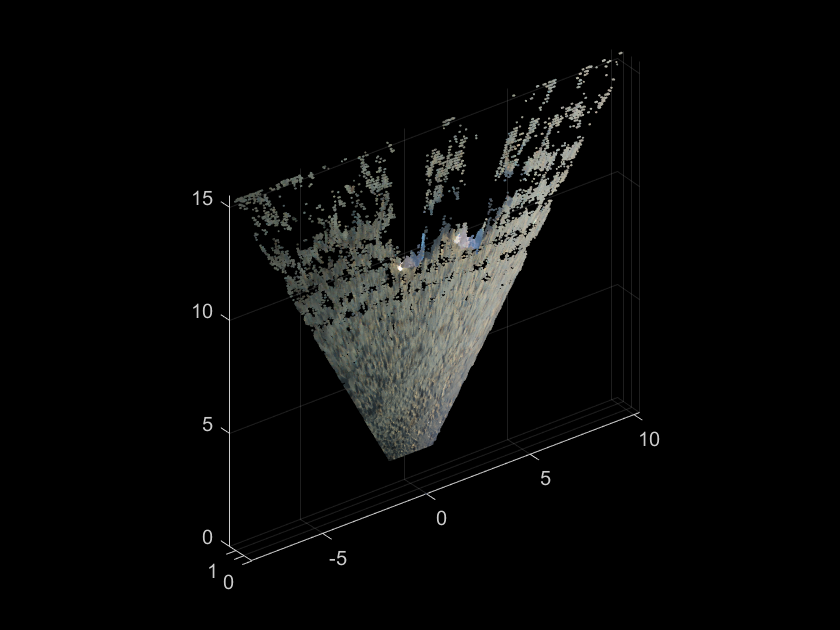

%original
ptCloudRef = pc1;
ptCloudCurrent = pc2;

% Preprocess the data by downsampling with a box grid filter and set the size of grid filter to be 5cm. 
% The grid filter divides the point cloud space into cubes. Points within each cube are combined into a single output point by averaging their X,Y,Z coordinates.
gridSize = 0.45;
fixed = pcdownsample(ptCloudRef, 'gridAverage', gridSize);
moving = pcdownsample(ptCloudCurrent, 'gridAverage', gridSize);

tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
ptCloudAligned = pctransform(ptCloudCurrent,tform);

mergeSize = 0.015;
ptCloud_firsttwo = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);
showPointCloud(ptCloud_firsttwo);

tform

tform =   rigid3d with properties:

       Rotation: [3×3 double]
    Translation: [-0.0407 -0.0050 0.0241]




tform;
accumTform = tform; 
ptCloudScene = ptCloud_firsttwo;


for i = 2:length(directory_of_images_small)
    tic
    %get the data of the next timestamp
    i
    ptCloudCurrent = char(directory_of_images(i));
    PC_next = makePC(ptCloudCurrent);
    
    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(PC_next, 'gridAverage', gridSize);
    
    % Apply ICP registration.
    tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
    

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = affine3d(tform.T * accumTform.T);
    ptCloudAligned = pctransform(PC_next, accumTform);
    
    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene, ptCloudAligned, mergeSize);
    toc
end

i = 2

Elapsed time is 31.396893 seconds.


i = 3

Elapsed time is 32.804880 seconds.


i = 4

Elapsed time is 30.193828 seconds.


i = 5

Elapsed time is 31.246978 seconds.


i = 6

Elapsed time is 46.090736 seconds.


i = 7

Elapsed time is 39.035754 seconds.


i = 8

Elapsed time is 30.033271 seconds.


i = 9

Elapsed time is 32.747299 seconds.


i = 10

Elapsed time is 35.990718 seconds.


i = 11

Elapsed time is 32.480818 seconds.


i = 12

Elapsed time is 33.498574 seconds.


i = 13

Elapsed time is 30.448671 seconds.


i = 14

Elapsed time is 30.276269 seconds.


i = 15

Elapsed time is 37.038880 seconds.


i = 16

Elapsed time is 40.814611 seconds.


i = 17

Elapsed time is 51.107326 seconds.


i = 18

Elapsed time is 62.353935 seconds.


i = 19

Elapsed time is 68.408050 seconds.


i = 20

Elapsed time is 59.722163 seconds.


i = 21

Elapsed time is 72.419017 seconds.


i = 22

Elapsed time is 70.698626 seconds.


i = 23

Elapsed time is 69.248101 seconds.


i = 24

Elapsed time is 74.265416 seconds.


i = 25

Elapsed time is 66.305027 seconds.


i = 26

Elapsed time is 69.347727 seconds.


i = 27

Elapsed time is 67.966921 seconds.


i = 28

Elapsed time is 61.063294 seconds.


i = 29

Elapsed time is 63.921332 seconds.


i = 30

Elapsed time is 42.158932 seconds.


i = 31

Elapsed time is 37.236691 seconds.


i = 32

Elapsed time is 32.495176 seconds.


i = 33

Elapsed time is 41.440825 seconds.


i = 34

Elapsed time is 33.006397 seconds.


i = 35

Elapsed time is 34.428339 seconds.


i = 36

Elapsed time is 36.457531 seconds.


i = 37

Elapsed time is 35.296457 seconds.


i = 38

Elapsed time is 34.762152 seconds.


i = 39

Elapsed time is 35.532572 seconds.


i = 40

Elapsed time is 34.513452 seconds.


i = 41

Elapsed time is 39.325869 seconds.


i = 42

Elapsed time is 35.445198 seconds.


i = 43

Elapsed time is 39.953538 seconds.


i = 44

Elapsed time is 33.139364 seconds.


i = 45

Elapsed time is 43.285915 seconds.


i = 46

Elapsed time is 33.373224 seconds.


i = 47

Elapsed time is 29.150800 seconds.


i = 48

Elapsed time is 28.707912 seconds.


i = 49

Elapsed time is 34.986435 seconds.


i = 50

Elapsed time is 28.809836 seconds.


i = 51

Elapsed time is 30.107634 seconds.


i = 52

Elapsed time is 28.033620 seconds.


i = 53

Elapsed time is 31.932495 seconds.


i = 54

Elapsed time is 29.504524 seconds.


i = 55

Elapsed time is 31.089867 seconds.


i = 56

Elapsed time is 27.994491 seconds.


i = 57

Elapsed time is 28.176643 seconds.


i = 58

Elapsed time is 28.602412 seconds.


i = 59

Elapsed time is 29.171843 seconds.


i = 60

Elapsed time is 34.089106 seconds.


i = 61

Elapsed time is 30.112256 seconds.


i = 62

Elapsed time is 30.031424 seconds.


i = 63

Elapsed time is 31.225819 seconds.


i = 64

Elapsed time is 29.441321 seconds.


i = 65

Elapsed time is 27.878276 seconds.


i = 66

Elapsed time is 31.439950 seconds.


i = 67

Elapsed time is 31.111407 seconds.


i = 68

Elapsed time is 29.378193 seconds.


i = 69

Elapsed time is 29.442889 seconds.


i = 70

Elapsed time is 31.393448 seconds.


i = 71

Elapsed time is 30.235877 seconds.


i = 72

Elapsed time is 30.068493 seconds.


i = 73

Elapsed time is 31.166573 seconds.


i = 74

Elapsed time is 28.328417 seconds.


i = 75

Elapsed time is 27.180058 seconds.


i = 76

Elapsed time is 29.932531 seconds.


i = 77

Elapsed time is 30.503810 seconds.


i = 78

Elapsed time is 30.856451 seconds.


i = 79

Elapsed time is 33.314176 seconds.


i = 80

Elapsed time is 30.668563 seconds.


i = 81

Elapsed time is 33.007543 seconds.


i = 82

Elapsed time is 31.525159 seconds.


i = 83

Elapsed time is 28.709799 seconds.


i = 84

Elapsed time is 28.547369 seconds.


i = 85

Elapsed time is 27.435124 seconds.


i = 86

Elapsed time is 30.505284 seconds.


i = 87

Elapsed time is 28.970928 seconds.


i = 88

Elapsed time is 28.658186 seconds.


i = 89

Elapsed time is 30.917209 seconds.


i = 90

Elapsed time is 36.557238 seconds.


i = 91

Elapsed time is 30.434258 seconds.


i = 92

Elapsed time is 31.470535 seconds.


i = 93

Elapsed time is 31.514935 seconds.


i = 94

Elapsed time is 31.596144 seconds.


i = 95

Elapsed time is 30.648830 seconds.


i = 96

Elapsed time is 33.586535 seconds.


i = 97

Elapsed time is 32.052756 seconds.


i = 98

Elapsed time is 28.445380 seconds.


i = 99

Elapsed time is 36.654663 seconds.


i = 100

Elapsed time is 33.892317 seconds.


i = 101

Elapsed time is 50.124717 seconds.


i = 102

Elapsed time is 53.627927 seconds.


i = 103

Elapsed time is 61.732639 seconds.


i = 104

Elapsed time is 64.900525 seconds.


i = 105

Elapsed time is 56.963069 seconds.


i = 106

Elapsed time is 40.929261 seconds.


i = 107

Elapsed time is 41.570302 seconds.


i = 108

Elapsed time is 47.705946 seconds.


i = 109

Elapsed time is 50.483739 seconds.


i = 110

Elapsed time is 53.213125 seconds.


i = 111

Elapsed time is 59.373546 seconds.


i = 112

Elapsed time is 45.031035 seconds.


i = 113

Elapsed time is 49.969657 seconds.


i = 114

Elapsed time is 36.037993 seconds.


i = 115

Elapsed time is 48.735938 seconds.


i = 116

Elapsed time is 53.292393 seconds.


i = 117

Elapsed time is 84.382442 seconds.


i = 118

Elapsed time is 56.872059 seconds.


i = 119

Elapsed time is 53.033034 seconds.


i = 120

Elapsed time is 60.645167 seconds.


i = 121

Elapsed time is 76.619956 seconds.


i = 122

Elapsed time is 41.759722 seconds.


i = 123

Elapsed time is 43.097194 seconds.


i = 124

Elapsed time is 36.189778 seconds.


i = 125

Elapsed time is 50.649664 seconds.


i = 126

Elapsed time is 49.405195 seconds.


i = 127

Elapsed time is 45.870660 seconds.


i = 128

Elapsed time is 47.355927 seconds.


i = 129

Elapsed time is 44.456400 seconds.


i = 130

Elapsed time is 41.144604 seconds.


i = 131

Elapsed time is 44.206421 seconds.


i = 132

Elapsed time is 45.390972 seconds.


i = 133

Elapsed time is 43.960587 seconds.


i = 134

Elapsed time is 45.427452 seconds.


i = 135

Elapsed time is 43.401125 seconds.


i = 136

Elapsed time is 45.980113 seconds.


i = 137

Elapsed time is 46.463476 seconds.


i = 138

Elapsed time is 43.411591 seconds.


i = 139

Elapsed time is 36.552705 seconds.


i = 140

Elapsed time is 38.165622 seconds.


i = 141

Elapsed time is 36.450438 seconds.


i = 142

Elapsed time is 41.601814 seconds.


i = 143

Elapsed time is 41.827757 seconds.


i = 144

Elapsed time is 39.032490 seconds.


i = 145

Elapsed time is 37.274895 seconds.


i = 146

Elapsed time is 36.428527 seconds.


i = 147

Elapsed time is 37.253976 seconds.


i = 148

Elapsed time is 35.392452 seconds.


i = 149

Elapsed time is 38.917285 seconds.


i = 150

Elapsed time is 43.820499 seconds.


i = 151

Elapsed time is 37.325148 seconds.


i = 152

Elapsed time is 37.180579 seconds.


i = 153

Elapsed time is 36.575746 seconds.


i = 154

Elapsed time is 39.401968 seconds.


i = 155

Elapsed time is 38.744837 seconds.


i = 156

Elapsed time is 37.931111 seconds.


i = 157

Elapsed time is 36.462143 seconds.


i = 158

Elapsed time is 47.190363 seconds.


i = 159

Elapsed time is 45.200994 seconds.


i = 160

Elapsed time is 38.275977 seconds.


i = 161

Elapsed time is 43.089385 seconds.


i = 162

Elapsed time is 36.023403 seconds.


i = 163

Elapsed time is 38.904930 seconds.


i = 164

Elapsed time is 40.302871 seconds.


i = 165

Elapsed time is 36.911600 seconds.


i = 166

Elapsed time is 44.034576 seconds.


i = 167

Elapsed time is 38.723287 seconds.


i = 168

Elapsed time is 38.614796 seconds.


i = 169

Elapsed time is 40.006557 seconds.


i = 170

Elapsed time is 38.840298 seconds.


i = 171

Elapsed time is 37.794602 seconds.


i = 172

Elapsed time is 39.651482 seconds.


i = 173

Elapsed time is 39.913297 seconds.


i = 174

Elapsed time is 41.983901 seconds.


i = 175

Elapsed time is 49.770346 seconds.


i = 176

Elapsed time is 44.360623 seconds.


i = 177

Elapsed time is 36.291447 seconds.


i = 178

Elapsed time is 36.312852 seconds.


i = 179

Elapsed time is 36.046493 seconds.


i = 180

Elapsed time is 37.007838 seconds.


i = 181

Elapsed time is 34.639586 seconds.


i = 182

Elapsed time is 34.691979 seconds.


i = 183

Elapsed time is 38.034143 seconds.


i = 184

Elapsed time is 39.332547 seconds.


i = 185

Elapsed time is 54.646174 seconds.


i = 186

Elapsed time is 43.894999 seconds.


i = 187

Elapsed time is 38.327803 seconds.


i = 188

Elapsed time is 38.940981 seconds.


i = 189

Elapsed time is 36.640504 seconds.


i = 190

Elapsed time is 36.147355 seconds.


i = 191

Elapsed time is 34.428232 seconds.


i = 192

Elapsed time is 35.784563 seconds.


i = 193

Elapsed time is 37.079058 seconds.


i = 194

Elapsed time is 37.068137 seconds.


i = 195

Elapsed time is 35.474437 seconds.


i = 196

Elapsed time is 34.453196 seconds.


i = 197

Elapsed time is 40.017372 seconds.


i = 198

Elapsed time is 37.463757 seconds.


i = 199

Elapsed time is 38.424348 seconds.


i = 200

Elapsed time is 37.634844 seconds.


i = 201

Elapsed time is 32.959235 seconds.


i = 202

Elapsed time is 36.796010 seconds.


i = 203

Elapsed time is 47.002311 seconds.


i = 204

Elapsed time is 39.543381 seconds.


i = 205

Elapsed time is 35.174892 seconds.


i = 206

Elapsed time is 35.367777 seconds.


i = 207

Elapsed time is 34.515801 seconds.


i = 208

Elapsed time is 35.028838 seconds.


i = 209

Elapsed time is 34.897358 seconds.


i = 210

Elapsed time is 37.297683 seconds.


i = 211

Elapsed time is 34.649783 seconds.


i = 212

Elapsed time is 37.760046 seconds.


i = 213

Elapsed time is 37.022936 seconds.


i = 214

Elapsed time is 36.878166 seconds.


i = 215

Elapsed time is 34.676411 seconds.


i = 216

Elapsed time is 34.606727 seconds.


i = 217

Elapsed time is 36.766936 seconds.


i = 218

Elapsed time is 32.861092 seconds.


i = 219

Elapsed time is 35.279064 seconds.


i = 220

Elapsed time is 33.094154 seconds.


i = 221

Elapsed time is 38.154551 seconds.


i = 222

Elapsed time is 35.050039 seconds.


i = 223

Elapsed time is 37.602031 seconds.


i = 224

Elapsed time is 36.682305 seconds.


i = 225

Elapsed time is 35.772717 seconds.


i = 226

Elapsed time is 35.177590 seconds.


i = 227

Elapsed time is 35.821081 seconds.


i = 228

Elapsed time is 34.750948 seconds.


i = 229

Elapsed time is 37.500770 seconds.


i = 230

Elapsed time is 34.653996 seconds.


i = 231

Elapsed time is 36.531236 seconds.


i = 232

Elapsed time is 33.058497 seconds.


i = 233

Elapsed time is 35.333063 seconds.


i = 234

Elapsed time is 37.863208 seconds.


i = 235

Elapsed time is 36.797173 seconds.


i = 236

Elapsed time is 36.841865 seconds.


i = 237

Elapsed time is 34.452798 seconds.


i = 238

Elapsed time is 40.643752 seconds.


i = 239

Elapsed time is 31.239107 seconds.


i = 240

Elapsed time is 30.333985 seconds.


i = 241

Elapsed time is 30.593276 seconds.


i = 242

Elapsed time is 32.203816 seconds.


i = 243

Elapsed time is 30.931200 seconds.


i = 244

Elapsed time is 28.773642 seconds.


i = 245

Elapsed time is 28.096324 seconds.


i = 246

Elapsed time is 29.599499 seconds.


i = 247

Elapsed time is 34.168843 seconds.


i = 248

Elapsed time is 34.179233 seconds.


i = 249

Elapsed time is 29.459994 seconds.


i = 250

Elapsed time is 31.841058 seconds.


i = 251

Elapsed time is 29.866584 seconds.


i = 252

Elapsed time is 28.293171 seconds.


i = 253

Elapsed time is 30.851269 seconds.


i = 254

Elapsed time is 30.690813 seconds.


i = 255

Elapsed time is 28.741540 seconds.


i = 256

Elapsed time is 30.215142 seconds.


i = 257

Elapsed time is 34.998106 seconds.


i = 258

Elapsed time is 30.750753 seconds.


i = 259

Elapsed time is 28.578867 seconds.


i = 260

Elapsed time is 31.374739 seconds.


i = 261

Elapsed time is 35.838618 seconds.


i = 262

Elapsed time is 30.379403 seconds.


i = 263

Elapsed time is 28.729816 seconds.


i = 264

Elapsed time is 29.005174 seconds.


i = 265

Elapsed time is 29.150460 seconds.


i = 266

Elapsed time is 30.867442 seconds.


i = 267

Elapsed time is 34.071514 seconds.


i = 268

Elapsed time is 30.390065 seconds.


i = 269

Elapsed time is 28.678648 seconds.


i = 270

Elapsed time is 29.676419 seconds.


i = 271

Elapsed time is 28.917755 seconds.


i = 272

Elapsed time is 32.651750 seconds.


i = 273

Elapsed time is 29.543192 seconds.


i = 274

Elapsed time is 30.208738 seconds.


i = 275

Elapsed time is 28.927138 seconds.


i = 276

Elapsed time is 29.782362 seconds.


i = 277

Elapsed time is 29.679973 seconds.


i = 278

Elapsed time is 29.681517 seconds.


i = 279

Elapsed time is 33.973392 seconds.


i = 280

Elapsed time is 30.732753 seconds.


i = 281

Elapsed time is 30.633130 seconds.


i = 282

Elapsed time is 28.819463 seconds.


i = 283

Elapsed time is 38.589461 seconds.


i = 284

Elapsed time is 31.635829 seconds.


i = 285

Elapsed time is 30.924743 seconds.


i = 286

Elapsed time is 31.286822 seconds.


i = 287

Elapsed time is 35.522450 seconds.


i = 288

Elapsed time is 29.556410 seconds.


i = 289

Elapsed time is 29.924942 seconds.


i = 290

Elapsed time is 35.301396 seconds.


i = 291

Elapsed time is 39.734243 seconds.


i = 292

Elapsed time is 33.916997 seconds.


i = 293

Elapsed time is 31.767993 seconds.


i = 294

Elapsed time is 31.292500 seconds.


i = 295

Elapsed time is 30.855417 seconds.


i = 296

Elapsed time is 34.233516 seconds.


i = 297

Elapsed time is 30.643262 seconds.


i = 298

Elapsed time is 29.502194 seconds.


i = 299

Elapsed time is 30.928243 seconds.


i = 300

Elapsed time is 30.680003 seconds.


i = 301

Elapsed time is 29.535045 seconds.


i = 302

Elapsed time is 30.500684 seconds.


i = 303

Elapsed time is 29.410441 seconds.


i = 304

Elapsed time is 30.144482 seconds.


i = 305

Elapsed time is 29.655137 seconds.


i = 306

Elapsed time is 29.614877 seconds.


i = 307

Elapsed time is 30.514857 seconds.


i = 308

Elapsed time is 30.786793 seconds.


i = 309

Elapsed time is 31.452150 seconds.


i = 310

Elapsed time is 29.175527 seconds.


i = 311

Elapsed time is 30.411457 seconds.


i = 312

Elapsed time is 31.150194 seconds.


i = 313

Elapsed time is 33.487728 seconds.


i = 314

Elapsed time is 32.523781 seconds.


i = 315

Elapsed time is 34.670004 seconds.


i = 316

Elapsed time is 31.553978 seconds.


i = 317

Elapsed time is 30.813001 seconds.


i = 318

Elapsed time is 30.068028 seconds.


i = 319

Elapsed time is 31.038658 seconds.


i = 320

Elapsed time is 30.395241 seconds.


i = 321

Elapsed time is 32.733056 seconds.


i = 322

Elapsed time is 29.307289 seconds.


i = 323

Elapsed time is 31.778068 seconds.


i = 324

Elapsed time is 33.548786 seconds.


i = 325

Elapsed time is 29.197737 seconds.


i = 326

Elapsed time is 33.228717 seconds.


i = 327

Elapsed time is 37.232727 seconds.


i = 328

Elapsed time is 32.158081 seconds.


i = 329

Elapsed time is 31.476812 seconds.


i = 330

Elapsed time is 35.601176 seconds.


i = 331

Elapsed time is 31.622240 seconds.


i = 332

Elapsed time is 32.340477 seconds.


i = 333

Elapsed time is 30.700860 seconds.


i = 334

Elapsed time is 28.714743 seconds.


i = 335

Elapsed time is 29.969152 seconds.


i = 336

Elapsed time is 36.600637 seconds.


i = 337

Elapsed time is 33.566787 seconds.


i = 338

Elapsed time is 32.275275 seconds.


i = 339

Elapsed time is 31.487200 seconds.


i = 340

Elapsed time is 34.293920 seconds.


i = 341

Elapsed time is 31.700514 seconds.


i = 342

Elapsed time is 33.104880 seconds.


i = 343

Elapsed time is 31.540560 seconds.


i = 344

Elapsed time is 32.321952 seconds.


i = 345

Elapsed time is 29.378131 seconds.


i = 346

Elapsed time is 30.814551 seconds.


i = 347

Elapsed time is 31.826621 seconds.


i = 348

Elapsed time is 30.036776 seconds.


i = 349

Elapsed time is 30.803981 seconds.


i = 350

Elapsed time is 32.946728 seconds.


i = 351

Elapsed time is 31.521763 seconds.


i = 352

Elapsed time is 31.639981 seconds.


i = 353

Elapsed time is 31.720138 seconds.


i = 354

Elapsed time is 31.263088 seconds.


i = 355

Elapsed time is 30.740921 seconds.


i = 356

Elapsed time is 30.747732 seconds.


i = 357

Elapsed time is 32.248951 seconds.


i = 358

Elapsed time is 30.401107 seconds.


i = 359

Elapsed time is 30.319465 seconds.


i = 360

Elapsed time is 36.581074 seconds.


i = 361

Elapsed time is 31.214099 seconds.


i = 362

Elapsed time is 32.437035 seconds.


i = 363

Elapsed time is 30.823459 seconds.


i = 364

Elapsed time is 39.234921 seconds.


i = 365

Elapsed time is 32.158245 seconds.


i = 366

Elapsed time is 34.741515 seconds.


i = 367

Elapsed time is 33.757642 seconds.


i = 368

Elapsed time is 33.673153 seconds.


i = 369

Elapsed time is 30.358013 seconds.


i = 370

Elapsed time is 33.613199 seconds.


i = 371

Elapsed time is 29.616282 seconds.


i = 372

Elapsed time is 34.546880 seconds.


i = 373

Elapsed time is 30.992712 seconds.


i = 374

Elapsed time is 29.790802 seconds.


i = 375

Elapsed time is 31.538649 seconds.


i = 376

Elapsed time is 30.647020 seconds.


i = 377

Elapsed time is 30.390050 seconds.


i = 378

Elapsed time is 33.205884 seconds.


i = 379

Elapsed time is 32.929204 seconds.


i = 380

Elapsed time is 33.321681 seconds.


i = 381

Elapsed time is 36.770668 seconds.


i = 382

Elapsed time is 33.935846 seconds.


i = 383

Elapsed time is 28.877229 seconds.


i = 384

Elapsed time is 31.214459 seconds.


i = 385

Elapsed time is 37.604602 seconds.


i = 386

Elapsed time is 30.641812 seconds.


i = 387

Elapsed time is 30.402768 seconds.


i = 388

Elapsed time is 31.761731 seconds.


i = 389

Elapsed time is 31.912012 seconds.


i = 390

Elapsed time is 30.034360 seconds.


i = 391

Elapsed time is 35.739923 seconds.


i = 392

Elapsed time is 29.799394 seconds.


i = 393

Elapsed time is 31.827748 seconds.


i = 394

Elapsed time is 30.743386 seconds.


i = 395

Elapsed time is 32.079113 seconds.


i = 396

Elapsed time is 32.099983 seconds.


i = 397

Elapsed time is 31.029742 seconds.


i = 398

Elapsed time is 34.688274 seconds.


i = 399

Elapsed time is 33.698663 seconds.


i = 400

Elapsed time is 33.493314 seconds.


i = 401

Elapsed time is 34.499921 seconds.


i = 402

Elapsed time is 35.080483 seconds.


i = 403

Elapsed time is 54.101418 seconds.


i = 404

Elapsed time is 40.070541 seconds.


i = 405

Elapsed time is 31.768725 seconds.


i = 406

Elapsed time is 33.619732 seconds.


i = 407

Elapsed time is 32.451569 seconds.


i = 408

Elapsed time is 36.186783 seconds.


i = 409

Elapsed time is 34.146170 seconds.


i = 410

Elapsed time is 32.447581 seconds.


i = 411

Elapsed time is 34.322934 seconds.


i = 412

Elapsed time is 38.404533 seconds.


i = 413

Elapsed time is 34.723726 seconds.


i = 414

Elapsed time is 31.190260 seconds.


i = 415

Elapsed time is 35.066963 seconds.


i = 416

Elapsed time is 36.467964 seconds.


i = 417

Elapsed time is 33.030887 seconds.


i = 418

Elapsed time is 33.946588 seconds.


i = 419

Elapsed time is 34.516747 seconds.


i = 420

Elapsed time is 33.311994 seconds.


i = 421

Elapsed time is 32.108728 seconds.


i = 422

Elapsed time is 34.841231 seconds.


i = 423

Elapsed time is 36.489715 seconds.


i = 424

Elapsed time is 33.458300 seconds.


i = 425

Elapsed time is 33.432867 seconds.


i = 426

Elapsed time is 39.985408 seconds.


i = 427

Elapsed time is 36.985053 seconds.


i = 428

Elapsed time is 34.951515 seconds.


i = 429

Elapsed time is 32.622572 seconds.


i = 430

Elapsed time is 32.589174 seconds.


i = 431

Elapsed time is 34.745733 seconds.


i = 432

Elapsed time is 39.276643 seconds.


i = 433

Elapsed time is 32.814205 seconds.


i = 434

Elapsed time is 36.019495 seconds.


i = 435

Elapsed time is 32.236831 seconds.


i = 436

Elapsed time is 33.270657 seconds.


i = 437

Elapsed time is 33.850125 seconds.


i = 438

Elapsed time is 33.228255 seconds.


i = 439

Elapsed time is 37.153147 seconds.


i = 440

Elapsed time is 35.482160 seconds.


i = 441

Elapsed time is 40.921881 seconds.


i = 442

Elapsed time is 31.153678 seconds.


i = 443

Elapsed time is 31.652310 seconds.


i = 444

Elapsed time is 35.860721 seconds.


i = 445

Elapsed time is 33.374608 seconds.


i = 446

Elapsed time is 36.274498 seconds.


i = 447

Elapsed time is 34.213922 seconds.


i = 448

Elapsed time is 33.753036 seconds.


i = 449

Elapsed time is 34.127488 seconds.


i = 450

Elapsed time is 34.785820 seconds.


i = 451

Elapsed time is 37.965358 seconds.


i = 452

Elapsed time is 34.666407 seconds.


i = 453

Elapsed time is 32.794028 seconds.


i = 454

Elapsed time is 35.514691 seconds.


i = 455

Elapsed time is 32.714387 seconds.


i = 456

Elapsed time is 32.887592 seconds.


i = 457

Elapsed time is 33.334736 seconds.


i = 458

Elapsed time is 36.625922 seconds.


i = 459

Elapsed time is 39.045434 seconds.


i = 460

Elapsed time is 34.526017 seconds.


i = 461

Elapsed time is 31.359944 seconds.


i = 462

Elapsed time is 33.373491 seconds.


i = 463

Elapsed time is 34.447117 seconds.


i = 464

Elapsed time is 34.875628 seconds.


i = 465

Elapsed time is 35.783001 seconds.


i = 466

Elapsed time is 34.099185 seconds.


i = 467

Elapsed time is 35.868071 seconds.


i = 468

Elapsed time is 33.558513 seconds.


i = 469

Elapsed time is 33.428626 seconds.


i = 470

Elapsed time is 30.898891 seconds.


i = 471

Elapsed time is 32.973859 seconds.


i = 472

Elapsed time is 34.602128 seconds.


i = 473

Elapsed time is 35.801867 seconds.


i = 474

Elapsed time is 36.645446 seconds.


i = 475

Elapsed time is 32.736208 seconds.


i = 476

Elapsed time is 31.965877 seconds.


i = 477

Elapsed time is 33.920657 seconds.


i = 478

Elapsed time is 31.569772 seconds.


i = 479

Elapsed time is 34.808156 seconds.


i = 480

Elapsed time is 31.791762 seconds.


i = 481

Elapsed time is 33.758779 seconds.


i = 482

Elapsed time is 31.977841 seconds.


i = 483

Elapsed time is 32.855031 seconds.


i = 484

Elapsed time is 34.921351 seconds.


i = 485

Elapsed time is 35.566573 seconds.


i = 486

Elapsed time is 43.159946 seconds.


i = 487

Elapsed time is 32.484474 seconds.


i = 488

Elapsed time is 31.953984 seconds.


i = 489

Elapsed time is 34.140254 seconds.


i = 490

Elapsed time is 32.165519 seconds.


i = 491

Elapsed time is 35.747366 seconds.


i = 492

Elapsed time is 31.713416 seconds.


i = 493

Elapsed time is 35.081809 seconds.


i = 494

Elapsed time is 35.014351 seconds.


i = 495

Elapsed time is 32.453406 seconds.


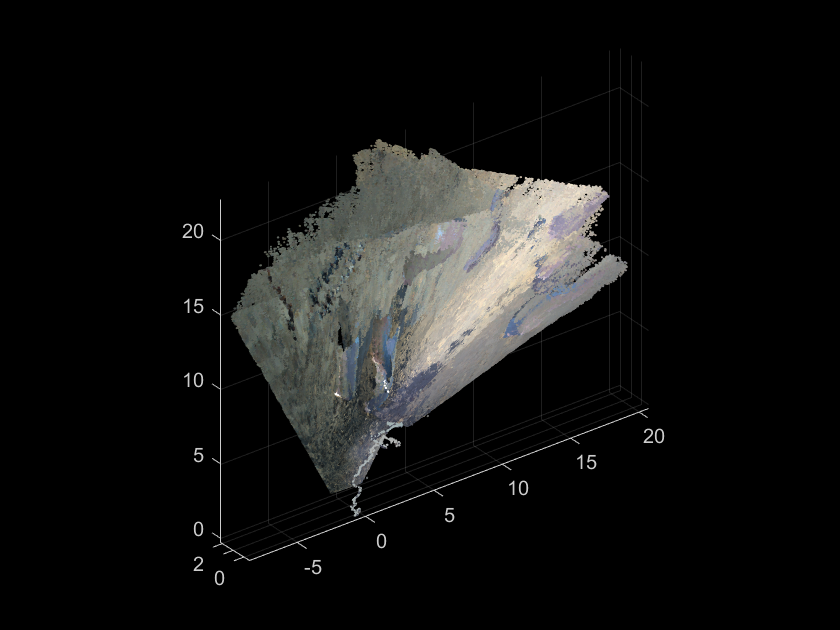

showPointCloud(ptCloudScene);

storedpc1 = ptCloudScene

storedpc1 =   pointCloud with properties:

     Location: [25227049×3 single]
        Color: [25227049×3 uint8]
       Normal: [0×3 single]
    Intensity: [0×1 single]
        Count: 25227049
      XLimits: [-8.4939 20.6830]
      YLimits: [-0.5862 2.1885]
      ZLimits: [-0.2371 22.7500]


ans =   Axes with properties:

             XLim: [-8.4939 20.6830]
             YLim: [-0.5862 2.1885]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


showPointCloud(storedpc1)

%downsample with weird thing
ptCloudRef = pc1;
ptCloudCurrent = pc2;

% Preprocess the data by downsampling with a box grid filter and set the size of grid filter to be 5cm. 
% The grid filter divides the point cloud space into cubes. Points within each cube are combined into a single output point by averaging their X,Y,Z coordinates.

fixed = pcdownsample(ptCloudRef,'nonuniformGridSample',20)

fixed =   pointCloud with properties:

     Location: [65536×3 single]
        Color: [65536×3 uint8]
       Normal: [65536×3 single]
    Intensity: []
        Count: 65536
      XLimits: [-8.2366 10.2579]
      YLimits: [0 1.3959]
      ZLimits: [0 15.4513]


moving = pcdownsample(ptCloudCurrent,'nonuniformGridSample',20)

moving =   pointCloud with properties:

     Location: [65536×3 single]
        Color: [65536×3 uint8]
       Normal: [65536×3 single]
    Intensity: []
        Count: 65536
      XLimits: [-8.4161 9.9815]
      YLimits: [0 1.3990]
      ZLimits: [0 15.4568]


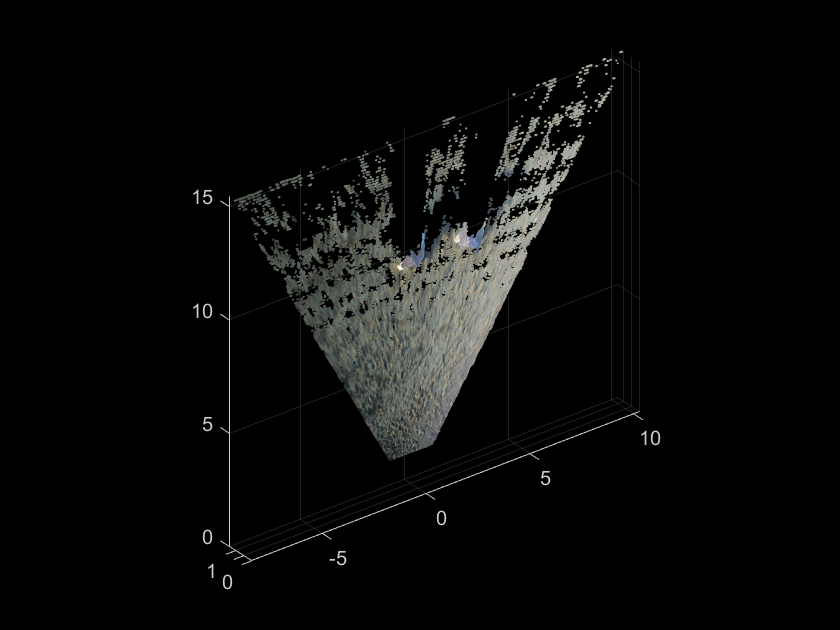



tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
ptCloudAligned = pctransform(ptCloudCurrent,tform);

mergeSize = 0.015;
ptCloud_firsttwo = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);
showPointCloud(ptCloud_firsttwo);

tform

tform =   rigid3d with properties:

       Rotation: [3×3 double]
    Translation: [-9.0904e-05 -2.7212e-04 9.2454e-04]




tform;
accumTform = tform; 
ptCloudScene = ptCloud_firsttwo;


for i = 2:length(directory_of_images_small)
    tic
    %get the data of the next timestamp
    i
    ptCloudCurrent = char(directory_of_images(i));
    PC_next = makePC(ptCloudCurrent);
    
    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(PC_next,'nonuniformGridSample',20);
    
    % Apply ICP registration.
    tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
    

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = affine3d(tform.T * accumTform.T);
    ptCloudAligned = pctransform(PC_next, accumTform);
    
    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene, ptCloudAligned, mergeSize);
    toc
end

i = 2

Elapsed time is 27.891601 seconds.


i = 3

Elapsed time is 28.005748 seconds.


i = 4

Elapsed time is 27.692852 seconds.


i = 5

Elapsed time is 28.671330 seconds.


i = 6

Elapsed time is 28.753059 seconds.


i = 7

Elapsed time is 29.604211 seconds.


i = 8

Elapsed time is 28.739223 seconds.


i = 9

Elapsed time is 29.249612 seconds.


i = 10

Elapsed time is 30.338894 seconds.


i = 11

Elapsed time is 32.309465 seconds.


i = 12

Elapsed time is 32.850472 seconds.


i = 13

Elapsed time is 31.458307 seconds.


i = 14

Elapsed time is 26.711681 seconds.


i = 15

Elapsed time is 32.616726 seconds.


i = 16

Elapsed time is 29.033546 seconds.


i = 17

Elapsed time is 24.841739 seconds.


i = 18

Elapsed time is 28.039498 seconds.


i = 19

Elapsed time is 29.677038 seconds.


i = 20

Elapsed time is 26.575221 seconds.


i = 21

Elapsed time is 29.672012 seconds.


i = 22

Elapsed time is 27.537698 seconds.


i = 23

Elapsed time is 26.886217 seconds.


i = 24

Elapsed time is 28.395960 seconds.


i = 25

Elapsed time is 27.922303 seconds.


i = 26

Elapsed time is 26.282065 seconds.


i = 27

Elapsed time is 26.393360 seconds.


i = 28

Elapsed time is 24.781525 seconds.


i = 29

Elapsed time is 26.904227 seconds.


i = 30

Elapsed time is 26.660469 seconds.


i = 31

Elapsed time is 27.569835 seconds.


i = 32

Elapsed time is 25.022559 seconds.


i = 33

Elapsed time is 30.166906 seconds.


i = 34

Elapsed time is 26.789883 seconds.


i = 35

Elapsed time is 27.928227 seconds.


i = 36

Elapsed time is 29.797853 seconds.


i = 37

Elapsed time is 27.983625 seconds.


i = 38

Elapsed time is 26.567024 seconds.


i = 39

Elapsed time is 27.691008 seconds.


i = 40

Elapsed time is 28.544431 seconds.


i = 41

Elapsed time is 30.598893 seconds.


i = 42

Elapsed time is 27.565952 seconds.


i = 43

Elapsed time is 31.252316 seconds.


i = 44

Elapsed time is 28.956028 seconds.


i = 45

Elapsed time is 34.385555 seconds.


i = 46

Elapsed time is 28.065689 seconds.


i = 47

Elapsed time is 28.916522 seconds.


i = 48

Elapsed time is 29.892699 seconds.


i = 49

Elapsed time is 34.747971 seconds.


i = 50

Elapsed time is 30.521344 seconds.


i = 51

Elapsed time is 32.253055 seconds.


i = 52

Elapsed time is 30.506390 seconds.


i = 53

Elapsed time is 33.836655 seconds.


i = 54

Elapsed time is 27.615402 seconds.


i = 55

Elapsed time is 29.489709 seconds.


i = 56

Elapsed time is 26.605727 seconds.


i = 57

Elapsed time is 27.440808 seconds.


i = 58

Elapsed time is 27.582662 seconds.


i = 59

Elapsed time is 27.072825 seconds.


i = 60

Elapsed time is 31.190797 seconds.


i = 61

Elapsed time is 29.168855 seconds.


i = 62

Elapsed time is 28.570536 seconds.


i = 63

Elapsed time is 30.025728 seconds.


i = 64

Elapsed time is 28.312601 seconds.


i = 65

Elapsed time is 26.125351 seconds.


i = 66

Elapsed time is 30.562870 seconds.


i = 67

Elapsed time is 29.060250 seconds.


i = 68

Elapsed time is 26.820591 seconds.


i = 69

Elapsed time is 27.484882 seconds.


i = 70

Elapsed time is 29.293404 seconds.


i = 71

Elapsed time is 29.771993 seconds.


i = 72

Elapsed time is 30.125699 seconds.


i = 73

Elapsed time is 29.519298 seconds.


i = 74

Elapsed time is 27.213407 seconds.


i = 75

Elapsed time is 25.990841 seconds.


i = 76

Elapsed time is 28.550884 seconds.


i = 77

Elapsed time is 29.839099 seconds.


i = 78

Elapsed time is 30.042679 seconds.


i = 79

Elapsed time is 31.375093 seconds.


i = 80

Elapsed time is 29.238625 seconds.


i = 81

Elapsed time is 26.910377 seconds.


i = 82

Elapsed time is 29.622491 seconds.


i = 83

Elapsed time is 27.524585 seconds.


i = 84

Elapsed time is 27.676198 seconds.


i = 85

Elapsed time is 26.524931 seconds.


i = 86

Elapsed time is 29.609287 seconds.


i = 87

Elapsed time is 28.766863 seconds.


i = 88

Elapsed time is 28.817504 seconds.


i = 89

Elapsed time is 29.913997 seconds.


i = 90

Elapsed time is 31.432689 seconds.


i = 91

Elapsed time is 29.155615 seconds.


i = 92

Elapsed time is 65.786486 seconds.


i = 93

Elapsed time is 30.267632 seconds.


i = 94

Elapsed time is 30.118025 seconds.


i = 95

Elapsed time is 29.284048 seconds.


i = 96

Elapsed time is 32.431248 seconds.


i = 97

Elapsed time is 29.136993 seconds.


i = 98

Elapsed time is 27.702295 seconds.


i = 99

Elapsed time is 27.616391 seconds.


i = 100

Elapsed time is 26.768092 seconds.


i = 101

Elapsed time is 27.090193 seconds.


i = 102

Elapsed time is 31.089998 seconds.


i = 103

Elapsed time is 28.187223 seconds.


i = 104

Elapsed time is 28.822306 seconds.


i = 105

Elapsed time is 30.134643 seconds.


i = 106

Elapsed time is 29.110295 seconds.


i = 107

Elapsed time is 28.707450 seconds.


i = 108

Elapsed time is 28.026786 seconds.


i = 109

Elapsed time is 76.283788 seconds.


i = 110

Elapsed time is 29.841954 seconds.


i = 111

Elapsed time is 30.874273 seconds.


i = 112

Elapsed time is 28.645370 seconds.


i = 113

Elapsed time is 31.123455 seconds.


i = 114

Elapsed time is 27.295376 seconds.


i = 115

Elapsed time is 28.699461 seconds.


i = 116

Elapsed time is 28.539371 seconds.


i = 117

Elapsed time is 34.166330 seconds.


i = 118

Elapsed time is 27.779552 seconds.


i = 119

Elapsed time is 29.114716 seconds.


i = 120

Elapsed time is 31.059871 seconds.


i = 121

Elapsed time is 38.314626 seconds.


i = 122

Elapsed time is 29.911479 seconds.


i = 123

Elapsed time is 30.702738 seconds.


i = 124

Elapsed time is 27.654065 seconds.


i = 125

Elapsed time is 31.160876 seconds.


i = 126

Elapsed time is 28.697322 seconds.


i = 127

Elapsed time is 28.963976 seconds.


i = 128

Elapsed time is 28.890079 seconds.


i = 129

Elapsed time is 27.758054 seconds.


i = 130

Elapsed time is 26.437021 seconds.


i = 131

Elapsed time is 29.182933 seconds.


i = 132

Elapsed time is 33.797875 seconds.


i = 133

Elapsed time is 33.949131 seconds.


i = 134

Elapsed time is 28.242048 seconds.


i = 135

Elapsed time is 26.920975 seconds.


i = 136

Elapsed time is 29.944335 seconds.


i = 137

Elapsed time is 28.244449 seconds.


i = 138

Elapsed time is 28.169015 seconds.


i = 139

Elapsed time is 27.793336 seconds.


i = 140

Elapsed time is 27.968027 seconds.


i = 141

Elapsed time is 27.459169 seconds.


i = 142

Elapsed time is 29.887128 seconds.


i = 143

Elapsed time is 31.497368 seconds.


i = 144

Elapsed time is 27.202530 seconds.


i = 145

Elapsed time is 68.690829 seconds.


i = 146

Elapsed time is 27.933700 seconds.


i = 147

Elapsed time is 27.845734 seconds.


i = 148

Elapsed time is 26.232609 seconds.


i = 149

Elapsed time is 29.052652 seconds.


i = 150

Elapsed time is 30.889419 seconds.


i = 151

Elapsed time is 63.043292 seconds.


i = 152

Elapsed time is 64.732630 seconds.


i = 153

Elapsed time is 27.264130 seconds.


i = 154

Elapsed time is 30.234303 seconds.


i = 155

Elapsed time is 28.559667 seconds.


i = 156

Elapsed time is 62.888598 seconds.


i = 157

Elapsed time is 26.920956 seconds.


i = 158

Elapsed time is 29.422674 seconds.


i = 159

Elapsed time is 65.751015 seconds.


i = 160

Elapsed time is 28.492257 seconds.


i = 161

Elapsed time is 68.720681 seconds.


i = 162

Elapsed time is 27.292305 seconds.


i = 163

Elapsed time is 64.476528 seconds.


i = 164

Elapsed time is 30.385139 seconds.


i = 165

Elapsed time is 26.979230 seconds.


i = 166

Elapsed time is 63.582510 seconds.


i = 167

Elapsed time is 64.782448 seconds.


i = 168

Elapsed time is 73.427901 seconds.


i = 169

Elapsed time is 29.705342 seconds.


i = 170

Elapsed time is 29.445682 seconds.


i = 171

Elapsed time is 28.281280 seconds.


i = 172

Elapsed time is 64.455559 seconds.


i = 173

Elapsed time is 66.043858 seconds.


i = 174

Elapsed time is 66.569834 seconds.


i = 175

Elapsed time is 66.627224 seconds.


i = 176

Elapsed time is 28.311484 seconds.


i = 177

Elapsed time is 29.038652 seconds.


i = 178

Elapsed time is 28.037019 seconds.


i = 179

Elapsed time is 30.053083 seconds.


i = 180

Elapsed time is 28.243576 seconds.


i = 181

Elapsed time is 63.605042 seconds.


i = 182

Elapsed time is 64.542058 seconds.


i = 183

Elapsed time is 30.019835 seconds.


i = 184

Elapsed time is 63.595904 seconds.


i = 185

Elapsed time is 29.529000 seconds.


i = 186

Elapsed time is 27.994347 seconds.


i = 187

Elapsed time is 30.366561 seconds.


i = 188

Elapsed time is 67.548377 seconds.


i = 189

Elapsed time is 28.817916 seconds.


i = 190

Elapsed time is 29.232173 seconds.


i = 191

Elapsed time is 64.021834 seconds.


i = 192

Elapsed time is 27.896117 seconds.


i = 193

Elapsed time is 29.748442 seconds.


i = 194

Elapsed time is 31.870567 seconds.


i = 195

Elapsed time is 29.486215 seconds.


i = 196

Elapsed time is 28.331177 seconds.


i = 197

Elapsed time is 66.899173 seconds.


i = 198

Elapsed time is 65.938143 seconds.


i = 199

Elapsed time is 31.233089 seconds.


i = 200

Elapsed time is 68.081412 seconds.


i = 201

Elapsed time is 66.949693 seconds.


i = 202

Elapsed time is 67.671359 seconds.


i = 203

Elapsed time is 72.426496 seconds.


i = 204

Elapsed time is 64.538460 seconds.


i = 205

Elapsed time is 64.327752 seconds.


i = 206

Elapsed time is 30.020863 seconds.


i = 207

Elapsed time is 66.311805 seconds.


i = 208

Elapsed time is 66.556012 seconds.


i = 209

Elapsed time is 104.186462 seconds.


i = 210

Elapsed time is 106.428829 seconds.


i = 211

Elapsed time is 104.409245 seconds.


i = 212

Elapsed time is 70.397666 seconds.


i = 213

Elapsed time is 71.754176 seconds.


i = 214

Elapsed time is 67.105472 seconds.


i = 215

Elapsed time is 98.504627 seconds.


i = 216

Elapsed time is 28.422072 seconds.


i = 217

Elapsed time is 105.379767 seconds.


i = 218

Elapsed time is 102.587438 seconds.


i = 219

Elapsed time is 104.527598 seconds.


i = 220

Elapsed time is 141.716192 seconds.


i = 221

Elapsed time is 140.408880 seconds.


i = 222

Elapsed time is 104.569286 seconds.


i = 223

Elapsed time is 107.822889 seconds.


i = 224

Elapsed time is 150.589138 seconds.


i = 225

Elapsed time is 144.243588 seconds.


i = 226

Elapsed time is 140.362106 seconds.


i = 227

Elapsed time is 104.044077 seconds.


i = 228

Elapsed time is 102.871532 seconds.


i = 229

Elapsed time is 151.774303 seconds.


i = 230

Elapsed time is 104.385904 seconds.


i = 231

Elapsed time is 101.585954 seconds.


i = 232

Elapsed time is 107.842776 seconds.


i = 233

Elapsed time is 106.400084 seconds.


i = 234

Elapsed time is 100.579286 seconds.


i = 235

Elapsed time is 66.415577 seconds.


i = 236

Elapsed time is 117.595083 seconds.


i = 237

Elapsed time is 27.322646 seconds.


i = 238

Elapsed time is 75.996282 seconds.


i = 239

Elapsed time is 28.561417 seconds.


i = 240

Elapsed time is 29.297511 seconds.


i = 241

Elapsed time is 30.809210 seconds.


i = 242

Elapsed time is 31.718235 seconds.


i = 243

Elapsed time is 33.295759 seconds.


i = 244

Elapsed time is 30.072822 seconds.


i = 245

Elapsed time is 27.757263 seconds.


i = 246

Elapsed time is 28.679963 seconds.


i = 247

Elapsed time is 32.361252 seconds.


i = 248

Elapsed time is 33.657442 seconds.


i = 249

Elapsed time is 28.695386 seconds.


i = 250

Elapsed time is 31.419377 seconds.


i = 251

Elapsed time is 30.193036 seconds.


i = 252

Elapsed time is 33.009187 seconds.


i = 253

Elapsed time is 31.557194 seconds.


i = 254

Elapsed time is 28.836932 seconds.


i = 255

Elapsed time is 27.675622 seconds.


i = 256

Elapsed time is 29.175858 seconds.


i = 257

Elapsed time is 35.149134 seconds.


i = 258

Elapsed time is 29.808157 seconds.


i = 259

Elapsed time is 29.590206 seconds.


i = 260

Elapsed time is 31.175270 seconds.


i = 261

Elapsed time is 36.043541 seconds.


i = 262

Elapsed time is 29.836710 seconds.


i = 263

Elapsed time is 27.794041 seconds.


i = 264

Elapsed time is 28.157669 seconds.


i = 265

Elapsed time is 28.474638 seconds.


i = 266

Elapsed time is 32.852831 seconds.


i = 267

Elapsed time is 35.522486 seconds.


i = 268

Elapsed time is 29.623039 seconds.


i = 269

Elapsed time is 28.940023 seconds.


i = 270

Elapsed time is 28.934936 seconds.


i = 271

Elapsed time is 29.447973 seconds.


i = 272

Elapsed time is 31.800865 seconds.


i = 273

Elapsed time is 29.424383 seconds.


i = 274

Elapsed time is 31.443798 seconds.


i = 275

Elapsed time is 28.825293 seconds.


i = 276

Elapsed time is 28.480055 seconds.


i = 277

Elapsed time is 29.205147 seconds.


i = 278

Elapsed time is 29.131807 seconds.


i = 279

Elapsed time is 33.583994 seconds.


i = 280

Elapsed time is 30.342351 seconds.


i = 281

Elapsed time is 30.329374 seconds.


i = 282

Elapsed time is 28.262696 seconds.


i = 283

Elapsed time is 37.593868 seconds.


i = 284

Elapsed time is 29.659172 seconds.


i = 285

Elapsed time is 27.986196 seconds.


i = 286

Elapsed time is 29.910335 seconds.


i = 287

Elapsed time is 34.364798 seconds.


i = 288

Elapsed time is 32.256690 seconds.


i = 289

Elapsed time is 30.634268 seconds.


i = 290

Elapsed time is 29.758920 seconds.


i = 291

Elapsed time is 29.487728 seconds.


i = 292

Elapsed time is 30.123631 seconds.


i = 293

Elapsed time is 29.544704 seconds.


i = 294

Elapsed time is 29.436712 seconds.


i = 295

Elapsed time is 29.351630 seconds.


i = 296

Elapsed time is 32.830970 seconds.


i = 297

Elapsed time is 29.028333 seconds.


i = 298

Elapsed time is 28.587422 seconds.


i = 299

Elapsed time is 28.939165 seconds.


i = 300

Elapsed time is 29.752022 seconds.


i = 301

Elapsed time is 28.688144 seconds.


i = 302

Elapsed time is 29.328082 seconds.


i = 303

Elapsed time is 27.446575 seconds.


i = 304

Elapsed time is 28.815545 seconds.


i = 305

Elapsed time is 30.135458 seconds.


i = 306

Elapsed time is 27.862383 seconds.


i = 307

Elapsed time is 29.389099 seconds.


i = 308

Elapsed time is 29.510903 seconds.


i = 309

Elapsed time is 29.523019 seconds.


i = 310

Elapsed time is 28.073089 seconds.


i = 311

Elapsed time is 29.756706 seconds.


i = 312

Elapsed time is 28.337005 seconds.


i = 313

Elapsed time is 31.109204 seconds.


i = 314

Elapsed time is 29.772071 seconds.


i = 315

Elapsed time is 32.712948 seconds.


i = 316

Elapsed time is 30.461449 seconds.


i = 317

Elapsed time is 29.438756 seconds.


i = 318

Elapsed time is 28.405712 seconds.


i = 319

Elapsed time is 30.196659 seconds.


i = 320

Elapsed time is 28.997204 seconds.


i = 321

Elapsed time is 29.508570 seconds.


i = 322

Elapsed time is 27.946291 seconds.


i = 323

Elapsed time is 29.176759 seconds.


i = 324

Elapsed time is 31.669959 seconds.


i = 325

Elapsed time is 27.491837 seconds.


i = 326

Elapsed time is 31.458834 seconds.


i = 327

Elapsed time is 35.238942 seconds.


i = 328

Elapsed time is 30.407641 seconds.


i = 329

Elapsed time is 29.520818 seconds.


i = 330

Elapsed time is 34.199856 seconds.


i = 331

Elapsed time is 30.050310 seconds.


i = 332

Elapsed time is 29.947073 seconds.


i = 333

Elapsed time is 29.243946 seconds.


i = 334

Elapsed time is 27.244371 seconds.


i = 335

Elapsed time is 29.323034 seconds.


i = 336

Elapsed time is 35.591752 seconds.


i = 337

Elapsed time is 32.010115 seconds.


i = 338

Elapsed time is 31.002575 seconds.


i = 339

Elapsed time is 30.805645 seconds.


i = 340

Elapsed time is 32.247806 seconds.


i = 341

Elapsed time is 31.043001 seconds.


i = 342

Elapsed time is 30.062709 seconds.


i = 343

Elapsed time is 30.199913 seconds.


i = 344

Elapsed time is 30.975504 seconds.


i = 345

Elapsed time is 28.189847 seconds.


i = 346

Elapsed time is 29.832124 seconds.


i = 347

Elapsed time is 30.923536 seconds.


i = 348

Elapsed time is 29.319204 seconds.


i = 349

Elapsed time is 30.213942 seconds.


i = 350

Elapsed time is 31.390969 seconds.


i = 351

Elapsed time is 29.697641 seconds.


i = 352

Elapsed time is 30.430690 seconds.


i = 353

Elapsed time is 29.572150 seconds.


i = 354

Elapsed time is 29.371182 seconds.


i = 355

Elapsed time is 28.767027 seconds.


i = 356

Elapsed time is 29.719517 seconds.


i = 357

Elapsed time is 30.639439 seconds.


i = 358

Elapsed time is 29.096686 seconds.


i = 359

Elapsed time is 28.928759 seconds.


i = 360

Elapsed time is 35.596291 seconds.


i = 361

Elapsed time is 28.077384 seconds.


i = 362

Elapsed time is 33.664389 seconds.


i = 363

Elapsed time is 29.145902 seconds.


i = 364

Elapsed time is 37.157038 seconds.


i = 365

Elapsed time is 32.252137 seconds.


i = 366

Elapsed time is 33.542041 seconds.


i = 367

Elapsed time is 32.159395 seconds.


i = 368

Elapsed time is 29.683788 seconds.


i = 369

Elapsed time is 29.235807 seconds.


i = 370

Elapsed time is 31.501039 seconds.


i = 371

Elapsed time is 28.147158 seconds.


i = 372

Elapsed time is 33.161198 seconds.


i = 373

Elapsed time is 28.501779 seconds.


i = 374

Elapsed time is 27.833162 seconds.


i = 375

Elapsed time is 29.932242 seconds.


i = 376

Elapsed time is 28.816384 seconds.


i = 377

Elapsed time is 28.827807 seconds.


i = 378

Elapsed time is 32.925736 seconds.


i = 379

Elapsed time is 29.629881 seconds.


i = 380

Elapsed time is 32.486407 seconds.


i = 381

Elapsed time is 31.331830 seconds.


i = 382

Elapsed time is 31.983362 seconds.


i = 383

Elapsed time is 27.308185 seconds.


i = 384

Elapsed time is 28.823588 seconds.


i = 385

Elapsed time is 41.554078 seconds.


i = 386

Elapsed time is 30.613867 seconds.


i = 387

Elapsed time is 28.309733 seconds.


i = 388

Elapsed time is 28.545704 seconds.


i = 389

Elapsed time is 29.952302 seconds.


i = 390

Elapsed time is 27.648454 seconds.


i = 391

Elapsed time is 33.481467 seconds.


i = 392

Elapsed time is 27.600521 seconds.


i = 393

Elapsed time is 29.652855 seconds.


i = 394

Elapsed time is 28.713355 seconds.


i = 395

Elapsed time is 30.574655 seconds.


i = 396

Elapsed time is 29.920299 seconds.


i = 397

Elapsed time is 28.506478 seconds.


i = 398

Elapsed time is 29.820946 seconds.


i = 399

Elapsed time is 31.639136 seconds.


i = 400

Elapsed time is 31.188862 seconds.


i = 401

Elapsed time is 31.795615 seconds.


i = 402

Elapsed time is 30.084243 seconds.


i = 403

Elapsed time is 33.256763 seconds.


i = 404

Elapsed time is 29.612628 seconds.


i = 405

Elapsed time is 28.089059 seconds.


i = 406

Elapsed time is 27.814934 seconds.


i = 407

Elapsed time is 28.413291 seconds.


i = 408

Elapsed time is 32.729993 seconds.


i = 409

Elapsed time is 31.669728 seconds.


i = 410

Elapsed time is 28.489613 seconds.


i = 411

Elapsed time is 29.639346 seconds.


i = 412

Elapsed time is 34.242243 seconds.


i = 413

Elapsed time is 29.939131 seconds.


i = 414

Elapsed time is 27.633464 seconds.


i = 415

Elapsed time is 29.785916 seconds.


i = 416

Elapsed time is 32.153973 seconds.


i = 417

Elapsed time is 28.544311 seconds.


i = 418

Elapsed time is 28.005787 seconds.


i = 419

Elapsed time is 30.635150 seconds.


i = 420

Elapsed time is 28.537688 seconds.


i = 421

Elapsed time is 28.260209 seconds.


i = 422

Elapsed time is 28.452143 seconds.


i = 423

Elapsed time is 31.608705 seconds.


i = 424

Elapsed time is 28.093516 seconds.


i = 425

Elapsed time is 29.518164 seconds.


i = 426

Elapsed time is 36.830951 seconds.


i = 427

Elapsed time is 32.730873 seconds.


i = 428

Elapsed time is 30.004904 seconds.


i = 429

Elapsed time is 28.974867 seconds.


i = 430

Elapsed time is 27.859528 seconds.


i = 431

Elapsed time is 30.696234 seconds.


i = 432

Elapsed time is 33.675797 seconds.


i = 433

Elapsed time is 28.154386 seconds.


i = 434

Elapsed time is 32.014981 seconds.


i = 435

Elapsed time is 27.959682 seconds.


i = 436

Elapsed time is 29.605450 seconds.


i = 437

Elapsed time is 30.568303 seconds.


i = 438

Elapsed time is 30.093312 seconds.


i = 439

Elapsed time is 33.232581 seconds.


i = 440

Elapsed time is 31.280723 seconds.


i = 441

Elapsed time is 34.971398 seconds.


i = 442

Elapsed time is 27.405912 seconds.


i = 443

Elapsed time is 27.715390 seconds.


i = 444

Elapsed time is 31.198638 seconds.


i = 445

Elapsed time is 29.887337 seconds.


i = 446

Elapsed time is 31.539619 seconds.


i = 447

Elapsed time is 30.251289 seconds.


i = 448

Elapsed time is 29.093747 seconds.


i = 449

Elapsed time is 30.321369 seconds.


i = 450

Elapsed time is 29.801623 seconds.


i = 451

Elapsed time is 33.435962 seconds.


i = 452

Elapsed time is 30.393793 seconds.


i = 453

Elapsed time is 29.130466 seconds.


i = 454

Elapsed time is 31.467438 seconds.


i = 455

Elapsed time is 28.169515 seconds.


i = 456

Elapsed time is 29.391596 seconds.


i = 457

Elapsed time is 30.614316 seconds.


i = 458

Elapsed time is 31.871156 seconds.


i = 459

Elapsed time is 34.203895 seconds.


i = 460

Elapsed time is 30.600157 seconds.


i = 461

Elapsed time is 28.006409 seconds.


i = 462

Elapsed time is 29.475284 seconds.


i = 463

Elapsed time is 30.410193 seconds.


i = 464

Elapsed time is 31.205996 seconds.


i = 465

Elapsed time is 32.164848 seconds.


i = 466

Elapsed time is 30.739152 seconds.


i = 467

Elapsed time is 31.276401 seconds.


i = 468

Elapsed time is 29.616500 seconds.


i = 469

Elapsed time is 30.528143 seconds.


i = 470

Elapsed time is 27.652329 seconds.


i = 471

Elapsed time is 29.307291 seconds.


i = 472

Elapsed time is 30.172360 seconds.


i = 473

Elapsed time is 32.453264 seconds.


i = 474

Elapsed time is 30.839366 seconds.


i = 475

Elapsed time is 28.953540 seconds.


i = 476

Elapsed time is 27.916999 seconds.


i = 477

Elapsed time is 28.837264 seconds.


i = 478

Elapsed time is 28.254761 seconds.


i = 479

Elapsed time is 31.117144 seconds.


i = 480

Elapsed time is 30.787434 seconds.


i = 481

Elapsed time is 30.428004 seconds.


i = 482

Elapsed time is 28.696391 seconds.


i = 483

Elapsed time is 29.077262 seconds.


i = 484

Elapsed time is 30.668772 seconds.


i = 485

Elapsed time is 29.333471 seconds.


i = 486

Elapsed time is 33.137298 seconds.


i = 487

Elapsed time is 31.564850 seconds.


i = 488

Elapsed time is 28.942980 seconds.


i = 489

Elapsed time is 31.204866 seconds.


i = 490

Elapsed time is 28.982132 seconds.


i = 491

Elapsed time is 32.129445 seconds.


i = 492

Elapsed time is 28.287824 seconds.


i = 493

Elapsed time is 31.031273 seconds.


i = 494

Elapsed time is 31.074346 seconds.


i = 495

Elapsed time is 28.999745 seconds.


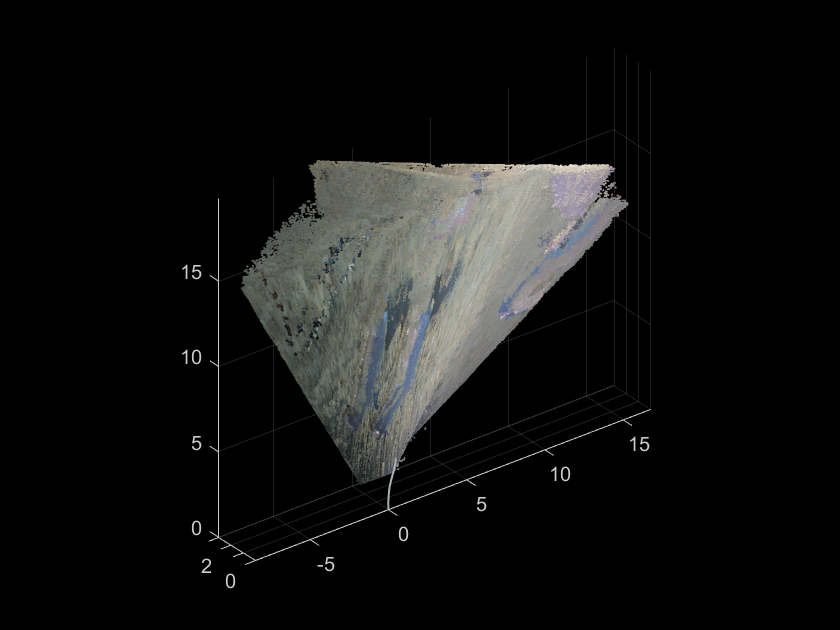

ans =   Axes with properties:

             XLim: [-8.5380 16.7417]
             YLim: [-0.0205 3.0140]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


showPointCloud(ptCloudScene)

storedpc2 = ptCloudScene

storedpc2 =   pointCloud with properties:

     Location: [10288962×3 single]
        Color: [10288962×3 uint8]
       Normal: [0×3 single]
    Intensity: [0×1 single]
        Count: 10288962
      XLimits: [-8.5380 16.7417]
      YLimits: [-0.0205 3.0140]
      ZLimits: [-3.9664e-04 19.8397]


showPointCloud(storedpc2);

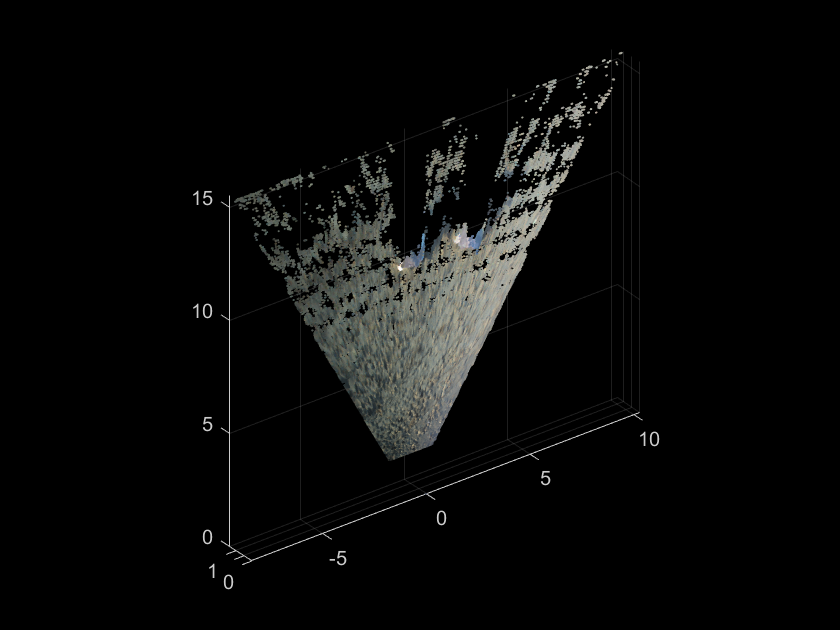

%original
ptCloudRef = pc1;
ptCloudCurrent = pc2;

% Preprocess the data by downsampling with a box grid filter and set the size of grid filter to be 5cm. 
% The grid filter divides the point cloud space into cubes. Points within each cube are combined into a single output point by averaging their X,Y,Z coordinates.
gridSize = 0.1;
fixed = pcdownsample(ptCloudRef, 'gridAverage', gridSize);
moving = pcdownsample(ptCloudCurrent, 'gridAverage', gridSize);

tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
ptCloudAligned = pctransform(ptCloudCurrent,tform);

mergeSize = 0.015;
ptCloud_firsttwo = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);
showPointCloud(ptCloud_firsttwo);

tform

tform =   rigid3d with properties:

       Rotation: [3×3 double]
    Translation: [-0.0502 -0.0011 0.0186]




tform;
accumTform = tform; 
ptCloudScene = ptCloud_firsttwo;


for i = 2:length(directory_of_images_small)
    tic
    %get the data of the next timestamp
    i
    ptCloudCurrent = char(directory_of_images(i));
    PC_next = makePC(ptCloudCurrent);
    
    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(PC_next, 'gridAverage', gridSize);
    
    % Apply ICP registration.
    tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
    

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = affine3d(tform.T * accumTform.T);
    ptCloudAligned = pctransform(PC_next, accumTform);
    
    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene, ptCloudAligned, mergeSize);
    toc
end

i = 2

Elapsed time is 25.802849 seconds.


i = 3

Elapsed time is 25.965659 seconds.


i = 4

Elapsed time is 25.272262 seconds.


showPointCloud(ptCloudScene);

storedpc3 = ptCloudScene

showPointCloud(storedpc3)

function [scenePC] = makePC(rangeImageLoc)
load('.\LocCam_calibration.mat');
if rangeImageLoc(end-4) == '0'
    left_img = imread(rangeImageLoc);
    right_img = imread(strcat(rangeImageLoc(1:end-5),'1.png'));
elseif rangeImageLoc(end-4) == '1'
    left_img = imread(strcat(rangeImageLoc(1:end-5),'0.png'));
    right_img = imread(rangeImageLoc);
else
    disp('No valid image pair was found at this file location.');
    quit;
end

[rectified_left, rectified_right] = rectifyStereoImages(left_img, right_img, stereoParams);

%make dispraity map
disparityMap = disparityBM(rgb2gray(rectified_left), rgb2gray(rectified_right));

%get pointcloud whith depth in meters
tussentijds_xyzPoints = reconstructScene(disparityMap,stereoParams)/1000;

%set depth boundary of 15 meters
Z = tussentijds_xyzPoints(:,:,3);
maskZ = repmat(Z > 0 & Z < 15,[1,1,3]);

%X = tussentijds_xyzPoints(:,:,1);
%maskX = repmat(X > -2 & X < 2,[1,1,3]);

%put mask on xyzPoints
tussentijds_xyzPoints(~maskZ) = 0;
%tussentijds_xyzPoints(~maskX) = 0;

scenePC_tussentijds = pointCloud(tussentijds_xyzPoints(:,:,1:3));

angle = -pi/10;
A = [1,0,0,0;0, cos(angle), sin(angle), 0;0, -sin(angle), cos(angle), 0;0 0 0 1];
gedraait = pctransform(scenePC_tussentijds, affine3d(A));

xyzPoints = gedraait.Location;
Y = xyzPoints(:,:,2);
maskY = repmat(Y > 0.5 & Y < 1.4,[1,1,3]);
xyzPoints(~maskY) = 0;

scenePC = pointCloud(xyzPoints, 'Color', rectified_left);
scenePC = removeInvalidPoints(scenePC);
scenePC = pcdenoise(scenePC, 'NumNeighbors',6);
end
